## Image Histogram Matching

In this problem, you will predetermine a threshold value and use this threshold and histogram matching to segment a new crack image.

You will determine a reference threshold value based on the following image, "refImg" (00004.jpg from the Concrete Crack dataset):

And apply this threshold to segment a new image, "newImg" (00143.jpg from the concrete crack dataset), with and without histogram matching.

Write code that will:

- Determine the reference threshold value from refImg.

- Use this threshold to segment newImg without histogram matching. Save the results as newImgBW.

- Match newImg's histogram to refImg's histogram. Then use the reference threshold to segment the histogram-matched crack image. 

- Save the results as matchImgBW.

## Read Images and Determine the Threshold

refImg=im2gray(imread("00004.jpg"));
newImg=im2gray(imread("00143.jpg"));

refThresh = graythresh(refImg)

refThresh = 0.4510

## Segment newImg without Histogram Matching

newImgBW = imbinarize(newImg,refThresh);

## Matching newImg's Histogram with refImg's Histogram

matchImg = imhistmatch(newImg, refImg);

## Segment the Histogram-matched Crack Image with Reference Threshold

matchImgBW=imbinarize(matchImg, refThresh);

## Show them Together to Compare

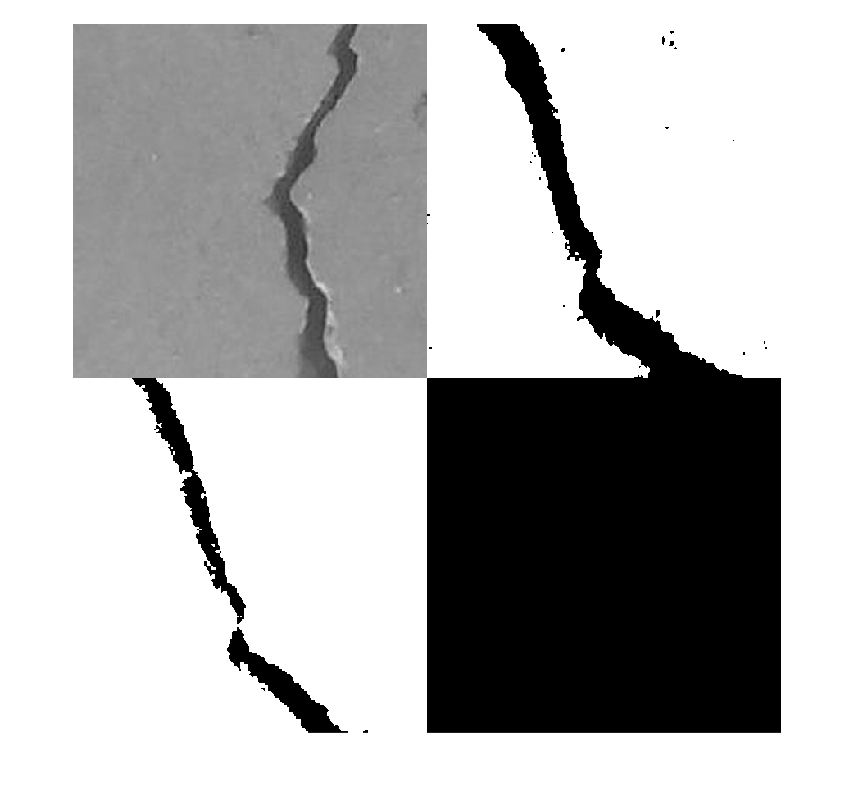

montage({refImg, newImgBW, matchImgBW})